clear all;
close all;
clc;

# Localgini Thresholding Method

This code is designed to execute the global thresholding algorithm.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Set up

The Gurobi solver is initialised, as well as COBRAToolbox.

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] GUROBI_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...Gurobi installed at this location? 
Licence file current? 


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

## Load the data

Gene expression data, the list of housekeeping genes and the metabolic model to be used are uploaded.

cd('C:/Users/pablo/OneDrive/Documentos/Systems_Biology_master/Github_folder/Internship/Data');
data = readtable("data_TPM.xlsx");

% Eisenberg Housekeeping gene list
h_k_g = readtable('NM2ENSG.xlsx');

% HKAtlas gene list
hk_gene_new = readtable('ENS_ID_HKG.xlsx');
hk_gene_new = table2cell(hk_gene_new);

% Joshi Housekeeping gene list
test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);

% Load GEMs models
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis, so it is recommended to remove these.

%[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
%model_p = fluxConsistModel; % load the new model with no blocked reactions
%save('model_p.mat', 'model');
model_p = load('model_p.mat');
model_p = model_p.model_p;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
%model_genes = model.genes;
cd('C:/Users/pablo/OneDrive/Documentos/Systems_Biology_master/Github_folder/Internship/Thresholding/Local_gini');

## Preprocessing

Expression data should be normalized to make the interpretation easier. A new matrix is created, including a first column called 'gene' including the ENSEMBL_IDs, and one column for each sample. The fene expression data is normalized based on this equation:

                                                                             
$$\text{normalized data} = \log_{10}(\text{data} + 1)$$


The 1 is added to avoid obtaining -inf values (log10(0)) that can affect the results. Those normalized values are added to their correspondent genes and samples. The normalized table is created. 

% Colect the data needed to create the table
sampleNames = data.Properties.VariableNames(2:end);
logged_data = log10(table2array(data(:, 2:end)) + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [data(:, 1), array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the gene expression dataset

Metabolic gene expression is extracted based on both, pruned and unpruned model. Those two matrices will be used afterwards.

%-------------------------------------- UNPRUNED MODEL -------------------------------------------%
geneExpressionMatrix = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1};
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data); 
    geneExpressionMatrix = [geneExpressionMatrix, geneExpression'];
    log_data.value = [];
end

% Convert the results into a table
metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', geneList, 'VariableNames', sampleNames);
% Delete the NaN values
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2)); % So we can use the local thresholding 

%-------------------------------------- PRUNED MODEL ---------------------------------------------%
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; 
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

% Convert the results into a table
metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);
% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

## LocalGini function

Obtain the Gini threshold and calculate which of the 3 values is the threshold for a specific gene

% Set the upper and lower threshold
up_percentage = 75;
low_percentage = 36;

% Use the localT2 function
[adjusted_matrix, expression_scoreMatrix] = localGini_function(metabolic_genes_P, metabolic_genes, low_percentage, up_percentage);

## Obtain core-genes

From the matrices that have been obtained, the ENSEMBL_IDs of the core-genes for each sample are taken.

gene_names = metabolic_genes_P.Properties.RowNames;

% Link with gene names
coreGenesStructure = cell(1, size(adjusted_matrix, 2));

for i = 1:size(adjusted_matrix, 2)
    activeGeneIndices = adjusted_matrix(:, i); % Gene active indexes
    coreGenesStructure{i} = gene_names(activeGeneIndices); % Gene active names
end
% save('coreGenesStructure_LG_N.mat', 'coreGenesStructure');

% Calculate the mean of core genes
mean_CoreGene = round(mean(cellfun(@length, coreGenesStructure)))

mean_CoreGene = 1273

## Map to Reactions

Using the output of the function for localGini, we set the input for the maExpressionToReactions function, which will return an array with the expression of each reaction in each sample.

% Create expressionData structure to use mapExpressionToReactions function
expressionData.gene = gene_names; 
expressionData.value = expression_scoreMatrix; 

%Initialize variables
Rxns_local25_75 = [];
geneUsed_local25_75 = {};
parsedGPR_local25_75 = {};

%Iterate over each sample
for i = 1:size(adjusted_matrix, 2)
    % Extract the expression data for the current sample
    expressionDataSample = struct();
    expressionDataSample.gene = expressionData.gene;
    expressionDataSample.value = expressionData.value(:, i); % Selecting the column for the current sample

    % Map expression data to reactions for the current sample
    [expressionRxns, parsedGPR, gene_used] = mapExpressionToReactions(model_p, expressionDataSample, false);
    Rxns_local25_75 = [Rxns_local25_75, expressionRxns]; % Store the mapped reactions
    geneUsed_local25_75{i} = gene_used; % Store the genes used in the mapping
    parsedGPR_local25_75{i} = parsedGPR; % Store the genes used in the mapping GO THROUGH IT!!!!!
end
% 
%Save the results
% save('Rxns_localG_N.mat', "Rxns_local25_75");
% save('geneUsed_localG_N.mat', 'geneUsed_local25_75');
% save('parsedGPR_localG_N.mat', 'parsedGPR_local25_75');

% Load them
% Rxns_local25_75 = load('Rxns_local25_75.mat');
% Rxns_local25_75 = Rxns_local25_75.Rxns_local25_75;
% geneUsed_local25_75 = load('geneUsed_local25_75.mat');
% geneUsed_local25_75 = geneUsed_local25_75.geneUsed_local25_75;
% parsedGPR_local25_75 = load('parsedGPR_local25_75.mat');
% parsedGPR_local25_75 = parsedGPR_local25_75.parsedGPR_local25_75;
% Check there are not repeated reactions


## Set the core reactions

From the matrix with the expression of the reactions, we establish as core-reactions those with a value greater than 1.

% Define variable
CoreReact_Sample = cell(size(sampleNames));

% Obtain core reactions names
for i = 1:size(adjusted_matrix, 2)
    activeReactions = find(Rxns_local25_75(:, i) >= 1);  % Active reactions indexes
    CoreReact_Sample{i} = model_p.rxns(activeReactions);  % Keep active reactions names for each sample
end
save('CoreReact_Sample_G.mat', 'CoreReact_Sample');

% Calculate the mean of core reactions
mean_coreReact = round(mean(cellfun(@length, CoreReact_Sample)))

mean_coreReact = 4657

# Compare housekeeping genes and reactions with core genes and reactions

## Housekeeping genes analysis

Now it starts the analysis for Housekeeping gene list. As it happens with the dataset, not all the housekeeping genes are related with the metabolism. We choose those ones that are related to the metabolism.

%hk_gene_new = table2cell(hk_gene_new);
hkg_met = model_p.genes(ismember(model_p.genes, test_HKG));

%----------------------- "OR" reactions approach ---------------------%
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react); %disp(housekeep_react_unique);
%--------------------- "AND" approach ----------------------------%
HK_rxns = find_housekeeping_reactions(model_p, hkg_met, 'strict')

HK_rxns = 1×2278 cell array
  Columns 1 through 2047

    {'MAR03905'}    {'MAR04099'}    {'MAR04281'}    {'MAR04388'}    {'MAR08357'}    {'MAR04360'}    {'MAR04363'}    {'MAR04365'}    {'MAR04368'}    {'MAR04371'}    {'MAR04373'}    {'MAR04381'}    {'MAR04391'}    {'MAR04396'}    {'MAR06412'}    {'MAR07747'}    {'MAR05399'}    {'MAR05400'}    {'MAR08568'}    {'MAR08569'}    {'MAR08570'}    {'MAR08571'}    {'MAR08572'}    {'MAR08573'}    {'MAR08574'}    {'MAR08575'}    {'MAR08576'}    {'MAR08577'}    {'MAR08578'}    {'MAR08579'}    {'MAR08581'}    {'MAR08580'}    {'MAR08582'}    {'MAR04130'}    {'MAR04131'}    {'MAR04132'}    {'MAR04414'}    {'MAR04416'}    {'MAR08766'}    {'MAR08767'}    {'MAR04297'}    {'MAR04316'}    {'MAR04385'}    {'MAR04386'}    {'MAR04387'}    {'MAR04402'}    {'MAR04706'}    {'MAR04591'}    {'MAR04592'}    {'MAR08341'}    {'MAR08727'}    {'MAR03853'}    {'MAR03854'}    {'MAR03855'}    {'MAR03857'}    {'MAR03859'}    {'MAR04087'}    {'MAR04091'}    {'MAR04143'}  

## Compare the number of housekeeping core genes

This part calculates how many metabolic housekeeping genes are considered core genes, and obtained the accuracy:

                                                                    
$$\text{accuracy} = \frac{\text{met\_core\_HKG}}{\text{total\_met\_HKG}}$$


housekep_core_gene_L = struct("numHousekeepingCoreGenes", [], 'housekeepingCoreGenes', [], 'percentage', []);
totalHousekeepingGenes = numel(hkg_met);

for i = 1:width(sampleNames)
    coreGenes = coreGenesStructure{i};
    housekeepingGeneNames = hkg_met;
    housekeepingInCore_g = ismember(housekeepingGeneNames, coreGenes);
    housekep_core_gene_L(i).numHousekeepingCoreGenes = sum(housekeepingInCore_g);
    housekep_core_gene_L(i).housekeepingCoreGenes = housekeepingGeneNames(housekeepingInCore_g);
    housekep_core_gene_L(i).percentage = (housekep_core_gene_L(i).numHousekeepingCoreGenes / totalHousekeepingGenes) * 100;
end

HK_G_acc_LT = [housekep_core_gene_L.percentage];
HK_G_acc_LT_col = HK_G_acc_LT(:);
T_Genes = table(HK_G_acc_LT_col, 'VariableNames', {'HK_G_acc_LG'});
writetable(T_Genes, "HK_G_acc_LG.xlsx", 'WriteRowNames', false);
save('housekep_core_gene_LG_N.mat', 'housekep_core_gene_L');

% Obtain the mean of housekeeping inclusion
mean_coreHKG = round(mean(arrayfun(@(x) x(1).numHousekeepingCoreGenes, housekep_core_gene_L)))

mean_coreHKG = 516

## Compare the number of housekeeping core reactions

This part calculates how many metabolic housekeeping reactions are considered core reactions, and obtained the accuracy:

                                                                    
$$\text{accuracy} = \frac{\text{met\_core\_HKR}}{\text{total\_met\_HKR}}$$


housekep_core_react_L = struct('numHousekeepingCoreReactions', [], 'housekeepingCoreReactions', [], 'percentage', []);
totalHousekeepingReactions = numel(housekeep_react_unique);

for i = 1:width(sampleNames)
    coreReactions = CoreReact_Sample{i};
    housekeepingInCore = ismember(housekeep_react_unique, coreReactions);
    housekep_core_react_L(i).numHousekeepingCoreReactions = sum(housekeepingInCore);
    housekep_core_react_L(i).housekeepingCoreReactions = housekeep_react_unique(housekeepingInCore);
    housekep_core_react_L(i).percentage = (housekep_core_react_L(i).numHousekeepingCoreReactions / totalHousekeepingReactions) * 100;
end

HK_R_acc_LT = [housekep_core_react_L.percentage];
HK_R_acc_LT_col = HK_R_acc_LT(:);
T_React = table(HK_R_acc_LT_col, 'VariableNames', {'HK_R_acc_LG'});
writetable(T_React, "HK_R_acc_LG.xlsx", 'WriteRowNames', false);
save('housekep_core_react_L_G.mat', 'housekep_core_react_L');

% Obtain the mean of housekeeping inclusion
mean_coreHKR = round(mean(arrayfun(@(x) x(1).numHousekeepingCoreReactions, housekep_core_react_L)))

mean_coreHKR = 2382

# Do the ubiquity score

This coefficient is needed to run mCADRE

row_names = model_p.rxns;
[coreRxns_binary, reactionFractions] = ubiquityScore_Thresholding(Rxns_local25_75,sampleNames, row_names);

## TEST FASTCORE

% From 7 to 12
% Obtain the names of the reactions (from coreRxns_binary) present in the sample
coreRxnNamesSelected = coreRxns_binary.Properties.RowNames(coreRxns_binary{:, 12} == 1);

% Find indexes for the reactions in the model
coreRxnIndices = find(ismember(model_p.rxns, coreRxnNamesSelected));

% Different parameters
% epsilon = 1e-1;
% printLevel = 2;

% Use FASTCORE funcion wiht the indexes to create teh Contex-Specific model
FASTCORE_MEAN_LG = fastcore(model_p, coreRxnIndices); % , epsilon, printLevel);

ans = 1×1 cell array
    {'MAR00463'}


% save('FASTCORE_IMR90_O3_LG.mat', 'FASTCORE_MEAN_LG');

## Gini coefficient for samples

% If data is a table, convert to numeric array
if istable(metabolic_genes_P)
    numericData = table2array(metabolic_genes_P);
else
    numericData = metabolic_genes_P;
end

% Preparing to store Gini coefficients
giniCoefficients = zeros(size(numericData, 1), 1);

% Apply the modified function giniUniform to each row
for i = 1:size(numericData, 1)
    giniCoefficients(i) = giniUniform(numericData(i, :), false);
end

## Plot it

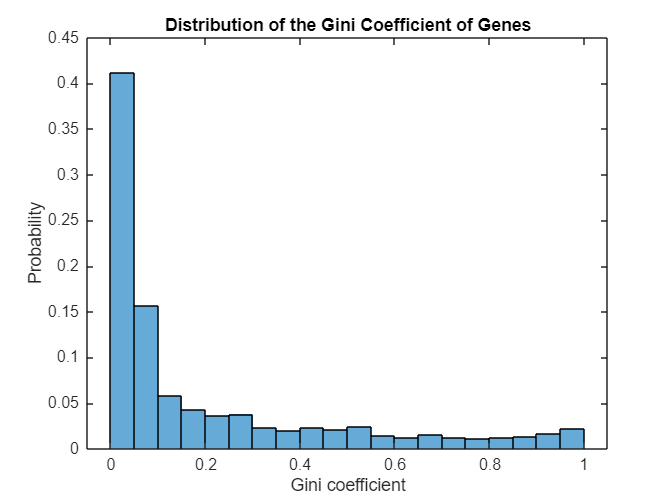

% Histogram of the Gini coefficients
figure;
histogram(giniCoefficients, 'Normalization', 'probability');
title('Distribution of the Gini Coefficient of Genes');
xlabel('Gini coefficient');
ylabel('Probability');
saveas(gcf, 'GiniCoefficientsDistribution.png');

# PIPELINE FROM THE PAPER

## Prepare the data

LocalGini needs a specific format in order to be used. In this section we configure the data in the structure format with the different sub-sections necessary to implement localGini 

% % Separating gene names and data
% genes = metabolic_genes.Properties.RowNames; % First column for gene names
% 
% % Get sample names (row names)
% context = metabolic_genes.Properties.VariableNames % Assuming that 'rownames' is a function or variable containing the row names
% 
% % Calculate the log10 of the fitted expression data
% value = metabolic_genes; % Normalize it
% 
% % Creating the structure
% geneExpression = struct;
% geneExpression.value = value;
% geneExpression.context = context;
% geneExpression.genes = genes;

## Repo pipeline

% % Choice of model extraction method (has to be anyone of ['FASTCORE','iMAT','MBA','GIMME','INIT','mCADRE'])
% MeM = 'FASTCORE';
% 
% % The context or samples that you are interested, in this case, all of them
% contexts = context;
% 
% % Set upper and lower thresholds
% ut = 75;
% lt = 25;
% 
% % Specifying where threshold has to be implied (1==> implied to genes; 2==> implied to enzymes; 3==> implied to reactions)
% ThS = 1; % impliying at gene level
% 
% % Reactions that are manually given higher importance
% biomass_id = find(strcmp(model.rxns,'biomass_reaction'));
% atp_demand_id = find(strcmp(model.rxns,'DM_atp_c_'));
% coreRxn=[biomass_id atp_demand_id];
% 
% % Tolerance level above which reactions are considered as expressed
% tol = 1e-4;
% 
% % Folder path to save the built models Here put your path to save the models, 
% % this way (\\) is for windows, for Linux, and I think for mac it should be (/)
% filename = 'C:\\Users\\PC\\OneDrive\\Documentos\\Systems_Biology_master\\Internship\\Internship\\Thresholding\\Local_gini\\';
% 
% % Building context-specific models
% % [Models,RxnImp] = buildContextmodels(geneExpression,model,MeM,contexts,ut,lt,ThS,coreRxn,filename,tol);
% % save('Models.mat', 'Models');
% % save('RxnImp.mat', 'RxnImp');
% RxI_check = load('RxnImp.mat');
% RxnImp = RxI_check.RxnImp;
% Model_check = load('Models.mat');
% Models = Model_check.Models;

## Housekeeping genes

Now it starts the analysis for Housekeeping gene list. As it happens with the dataset, not all the housekeeping genes are related with the metabolism. We choose those ones that are related to the metabolism.

% ens_hkg = h_k_g.converted_alias; 
% index_names = ismember(ens_hkg, genes);
% met_hkg = ens_hkg(index_names);
% 
% % Find reactions from the housekeeping genes
% reactions_hkg = findRxnsFromGenes_Alicia(model, met_hkg);
% 
% %Create an array with all the housekeeping reactions
% fields = fieldnames(reactions_hkg); 
% housekeep_react = {}; 
% 
% for i = 1:length(fields)
%     field = fields{i}; 
%     cellArray = reactions_hkg.(field); 
% 
%     for j = 1:size(cellArray, 1)
%         firstcol = cellArray{j, 1}; 
%         housekeep_react{end+1, 1} = firstcol;
%     end
% end
% housekeep_react;
% 
% % Finding unique elements and their frequency
% [uniques, ~, index] = unique(housekeep_react);

## Check the housekeeping core genes

This part of the code gives the percentage of metabolic core-housekeeping genes out of the total amount of metabolic housekeeping genes 

% num_models = length(Models);
% results = zeros(num_models, 1); 
% 
% for i = 1:num_models
%     current_model = Models{i};
% 
%     if isfield(current_model, 'genes')
%         genes_model = current_model.genes;
% 
%         num_coincidences = sum(ismember(genes_model, met_hkg));
% 
%         percentage_coincidences = (num_coincidences / length(met_hkg)) * 100;
% 
%         results(i) = percentage_coincidences;
%     else
%         results(i) = NaN;
%     end
% end
% HK_G_accuracy = array2table(results, 'VariableNames', {'PercentageCoincidences'});
% 
% HK_G_acc_LG = [HK_G_accuracy.PercentageCoincidences];
% HK_G_acc_LG_col = HK_G_acc_LG(:);
% T_Gene = table(HK_G_acc_LG_col, 'VariableNames', {'HK_G_acc_LG'});
% writetable(T_Gene, "HK_G_acc_LG.xlsx", 'WriteRowNames', false);

## Check the housekeeping core reactions

This part of the code gives the percentage of metabolic core-housekeeping reactions out of the total amount of metabolic housekeeping reactions. 

% num_models = length(Models);
% results = zeros(num_models, 1); 
% for i = 1:num_models
%     current_model = Models{i};
% 
%     if isfield(current_model, 'rxns')
%         reactions_model = current_model.rxns;
% 
%         num_coincidences = sum(ismember(reactions_model, uniques));
% 
%         percentage_coincidences = (num_coincidences / length(uniques)) * 100;
% 
%         results(i) = percentage_coincidences;
%     else
%         results(i) = NaN;
%     end
% end
% HK_R_accuracy = array2table(results, 'VariableNames', {'PercentageCoincidencesReactions'});
% 
% HK_R_acc_LG = [HK_R_accuracy.PercentageCoincidencesReactions];
% HK_R_acc_LG_col = HK_R_acc_LG(:);
% T_React = table(HK_R_acc_LG_col, 'VariableNames', {'HK_R_acc_LG'});
% writetable(T_React, "HK_R_acc_LG.xlsx", 'WriteRowNames', false);
% 
% 

# Gini coefficient for samples

% % If data is a table, convert to numeric array
% if istable(metabolic_genes_P)
%     numericData = table2array(metabolic_genes_P);
% else
%     numericData = metabolic_genes_P;
% end
% 
% % Preparing to store Gini coefficients
% giniCoefficients = zeros(size(numericData, 1), 1);
% 
% % Apply the modified function giniUniform to each row
% for i = 1:size(numericData, 1)
%     giniCoefficients(i) = giniUniform(numericData(i, :), false);
% end

## Plot it

% % Histogram of the Gini coefficients
% figure;
% histogram(giniCoefficients, 'Normalization', 'probability');
% title('Distribution of the Gini Coefficient of Genes');
% xlabel('Gini coefficient');
% ylabel('Probability');
% saveas(gcf, 'GiniCoefficientsDistribution.png');